# Figure 5BCD

Calculates the correlation matrix and Hedges'G for each pair of experiment, comapring the LG and MG injections in ChAT mice

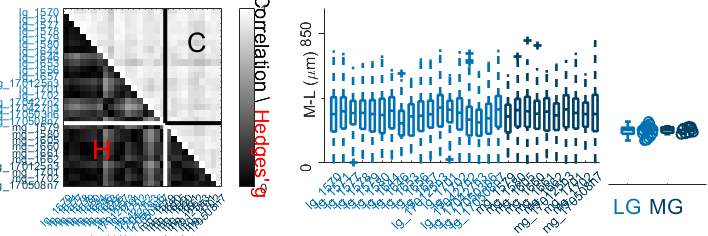

% plots correlation matrix for all experiments
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir


     dn = {[masterdir,'lg_chat\'],...
        [masterdir,'mg_chat\'};%,...
    ndir = length(dn);
    for i = 1:ndir
        labels{i} =  [extractBetween(dn{i},'data/','/xyz'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
    end



%%%%%%%%%%%%%%% switch to go straight to figure, rather than redoing
%%%%%%%%%%%%%%% calculations
readdata = 1;
%%%%%%%%%%%%%%%%

% figure settings
nr1 = 1;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 0;  % if concat=1 concatenates all files in directory
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [5,5];          % kernel size
res = [20,20]; % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if readdata

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 
[allins,allmns] = poolfun(dn,1); % ins and mns have the same dimensions 


for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% color settings
firstcolor = [0, 114, 178]/255;  %blu = GS
secondcolor = [230, 159, 0]/255; %orange = TA
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
seconddark = [180/255, 100/255, 0]; %dark orange = TA excitatory or PL

%allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for GS and TA
allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(firstdark,nfiles(2),1)); % for other pairs of muscles

ndir = length(dn);
ext = 'xlsx';

for i = 1:ndir
files_{i} = dir([dn{i},'*.',ext]);
end
gsins = [];
for i = 1:nfiles(1)
        gsname{i} = files_{1}(i).name;
        gsname{i} = extractBefore(gsname{i},'_n');
        gsname{i} = strrep(gsname{i},'gs','lg');
        gsname{i} = insertBefore(gsname{i}, 'lg','\color[rgb]{0.0,0.4471,0.6980}'); %= [0, 114, 178]/255;  %blu = 2nd directory = GS
        gsins = vertcat(gsins,ins{1}{i});
end
tains = [];
for i = 1:nfiles(2)
        taname{i} = files_{2}(i).name;
        taname{i} = extractBefore(taname{i},'_n');
        taname{i} = insertBefore(taname{i}, 'mg','\color[rgb]{0, 0.2533, 0.3956}'); % =[230, 159, 0]/255; %orange = 1st directory = TA
        tains = vertcat(tains,ins{2}{i});
end
names = horzcat(gsname, taname);
names = insertBefore(names,'_','\');


for i = 1:ndir
    for j = 1:nfiles(i)
       median_ml{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0,1));
    end
end



gck = gckernel();
setKernel(gck,ker);
setResd(gck,res);
junk = gck.convolve([allins{1}{1}(:,1)' ; allins{1}{1}(:,2)']); %intializes values of bins


% method 1
for i = 1:ndir
    for j = 1:nfiles(i)
        conv_result1{i}{j} = gck.convolve ([ins{i}{j}(:,1)';ins{i}{j}(:,2)']);
    end
end

% Lines up the files from the two direcotries to give a single matrix
for  i = 1:ndir
    for j = 1:nfiles(i)
        j+(i-1)*nfiles(ndir-1);
        conv_result_all{j+(i-1)*nfiles(ndir-1)} =conv_result1{i}{j};
        conv_result_ml{j+(i-1)*nfiles(ndir-1)} =sum(conv_result1{i}{j},1);
        ins_all{j+(i-1)*nfiles(ndir-1)} = ins{i}{j};
    end
end

ins_all_mat=[];
for i = 1:size(ins_all,2)
    ins_all_mat = nanhcat(ins_all_mat,ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1));
    ins_all_d_ipsi{i} = ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1); %selects x coordinates for neurons in the ipsi dorsal quaadrant
end

for i = 1: size(conv_result_all,2)
    for j = 1:size(conv_result_all,2)
       
     %CXYconv(i,j) = corr2(conv_result_all{i},conv_result_all{j}); % uses the mean as center of distributions
     CXYconv(i,j) = corr2median(conv_result_all{i},conv_result_all{j}); % uses the median as center of distributions
%      [HKS(i,j), pKS(i,j), KSstatistic] = kstest2(conv_result_ml{i}, conv_result_ml{j});  
%      [pperm(i,j), observeddifference, effectsize] = permutationTest(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1),1000);
%      [pranksum_x(i,j), Hranksum_x(i,j),ranksumstatistic_x(i,j)] = ranksum(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1));  
     hedges(i,j) = hedges_fun(ins_all_d_ipsi{i},ins_all_d_ipsi{j});
     
    end
end

else
end

f1 = figure;
%set(f1,'Position',[1 1 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(1,[0.24,0.12],[1.05,0.84]);
Panels.tweak(2,[0.36,0.],[1.3,0.95]);
Panels.tweak(3,[0.55,0.13],[0.5,0.84]);

% correlation panel;
%hmap =heatmap(CXYHIST,'XDisplayLabels',names, 'YDisplayLabels',names, 'CellLabelColor','r');
h =1;
corr_fig = Panels.setPanel(h);

%define rectangular matrix. the 'skip varaible adds whites on the digaonal
%to separate Hedges and correlation
skip = 0;
frame = zeros(size(conv_result_all,2),size(conv_result_all,2)+skip);
frame_corr = frame+ horzcat(zeros(size(conv_result_all,2),skip),triu(CXYconv));
frame_corr_hedges = frame_corr + horzcat(tril(hedges),zeros(size(conv_result_all,2),skip));

%defines colormap (0 is white, -1 and 1 are black)

bl_to_white = find(frame_corr_hedges==0);
frame_corr_hedges(bl_to_white)=1;
mapcorr = imagesc(abs(frame_corr_hedges),[0,1]);
hh = colormap(gray);
cmap = vertcat(hh,flipud(hh));
colormap(gray);

ax = gca;
 set (ax,'YTick',1:sum(nfiles),'YTickLabel',names,'XTick',1:sum(nfiles),'XTickLabel',names,...
     'XTickLabelRotation', 45);
hold on
cbcorr = colorbar;
set(cbcorr,'FontSize',10, 'Ticks',[0,1] );
cbcorr.Label.String = {'\color[rgb]{0,0,0}Correlation \\ \color[rgb]{1,0,0}Hedges'' g'};
cbcorr.Label.FontSize = 15;
cbcorr.Label.Rotation = -90;
cbcorr.Label.Position = [2.2879 0.5000 0];
%left bottom
ph = plot([nfiles(1)+0.5,nfiles(1)+0.5],[nfiles(1)-0.5,sum(nfiles)+0.5],'w','LineWidth',3); %vertical
plot([1-0.5,nfiles(1)+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'w','LineWidth',3); %horizontal
%caxis([0,1]);
%top right
ph = plot([nfiles(1)+skip+0.5,nfiles(1)+skip+0.5],[1-0.5,nfiles(1)+0.5],'k','LineWidth',3); %vertical
plot([nfiles(1)+skip+0.5,sum(nfiles)+skip+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'k','LineWidth',3); %horizontal
colormap(gray)
caxis([0,1]);
txtshift = 0.8;
text( (1-txtshift)*sum(nfiles),txtshift*sum(nfiles),'\fontname{arial}\color[rgb]{1,0,0}H','FontSize',20)
text(txtshift*sum(nfiles),(1-txtshift)*sum(nfiles),'\fontname{arial}\color[rgb]{0,0,0}C','FontSize',20)

h =2;
allins_fig = Panels.setPanel(h);
bpall = boxplot(ins_all_mat,'Color',allcolor, 'Symbol','+');
set(bpall,{'linew'},{2})
axall=gca;
set(axall,'XLim',[0,nfiles(1)+nfiles(2)+0.5],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTick',1:sum(nfiles),'XTickLabel',names, 'XTickLabelRotation', 45,...
    'YTick', [0,0.5], 'YTickLabels',  [0,850],...
    'YTickLabelRotation', 90);
          set(axall.YLabel,'Interpreter','tex');
         axall.YLabel.String = 'M-L (\mum)';
         axall.YLabel.Position = [-0.5165 0.306];
         axall.YAxis.FontSize = 11;
         axall.YAxis.FontName = 'arial';
         axall.YAxis.MinorTick = 'on';
         axall.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         axall.YAxis.TickDirection = 'out';
         axall.YAxis.TickLength = [0.0200 .3250];
box off

h =3;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml{1}', median_ml{2}'),'Color',[firstcolor;firstdark],'Symbol','+');
set(bp,{'linew'},{2})
ax3 = gca;
set(ax3,'XLim',[0.5,3],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTickLabel',{'\color[rgb]{0.0,0.4471,0.6980}LG', '\color[rgb]{0, 0.2533, 0.3956}MG'},...
    'FontSize',16);
ax3.YAxis.Visible = 'off';
hold on
ps = dischart(nanhcat(median_ml{1}', median_ml{2}'),[1.5,2.5],0.4,[],'','','o');
set(ps{1},'MarkerEdgeColor',firstcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',firstdark,'LineWidth',1.5, 'MarkerSize',7);
box off




Panels.addPanels();